addpath('/home/bogdan/.matlab/spm/spm12');
addpath(genpath('/home/bogdan/.matlab/canlab/CanlabCore'));
addpath(genpath('/home/bogdan/.matlab/canlab/Neuroimaging_Pattern_Masks'));
addpath(genpath('/home/bogdan/.matlab/canlab/canlab_single_trials'));
addpath(genpath('/home/bogdan/.matlab/canlab/canlab_single_trials_private'));

## Introduction

Let's assume you've run a volumetric analysis registered to a MNI template and you want to render this to a surface. This process is complex. 

3D graphics are represented as teselations, a mixture of vertex coordintaes and edges connecting adjacent vertices. Consider the central sulcus for instance, you may have multiple vertices in close proximity on opposite sulcal banks but these should not be connected, while proximal vertices on the same sulcal bank should be. That's what the tesellation achieves. To render from a volumetric image to a surface then you need a tesellation model of that surface along with vertex coordinates that coincide with your volumetric data. This is what freesurfer produces when you run surface segmentation: it generates a subject specific surface tesselation where the surface vertices overlap with coordinates in the volumetric nifti file from which the surface was generated. This allows direct sampling of volumetric data (e.g. BOLD timeseries aligned to the T1 used for surface modeling) to the surface, +/- interpolation among neighboring voxels. 

You can easily resample data from a T1 to its freesurfer surface model (although out of scope for this tutorial, look into the mri_surf2vol CLI), but once you've transformed your subject specific image into MNI space for group analysis you lose this possibility. There are group surface templates like the Conte69 template used by freesurfer and HCP, but these surfaces do not have vertices that correspond in any systematic way with those of any MNI template. In fact the radii aren't even the same as the MNI surface cortical ribbon. Most surface rendering options in canlab tools presume that the surface models used (most often BigBrain from the Julich institute) have vertices that overlap with MNI template gray matter ribbons, but this is not the case. Consequently the renderings are not veritical, not even in the assymptotic limit of infinite participants or infinite studies. They're systematically wrong. Thankfully there are principled ways to map from MNI space to a surface model which are built into canlab tools, if you know where to look.

#### Code map

There are a variety of tools that can accomplish rendering on slices (montages) and surfaces.  The latter are the main focus here. The code is designed to allow multiple entry points, and let you use high-level functions to run default options with simple code -- e.g., you can create a whole "scene" with multiple surfaces, montages, and figure windows using the ***fmridisplay*** object class and ***canlab_results_fmridisplay. ***Then you can render activation maps onto these surfaces.

#### Load sample dataset

First, we'll load a sample dataset to work with:

% load a dataset 
img = load_image_set('emotionreg');

% now let's get a mean image and thresholded t image to work with
mean_img = mean(img);
t = ttest(img);
t = threshold(t, 0.005, 'unc');

## Direct rendering to a MNI template surface segmentation

The simplest approach is to use freesurfer to segment a MNI template and then do a direct mapping from your MNI space brains to that template. As long as your segmentation is applied to the same template you used to do spatial normalization of your data this will work. Note however that there are multiple MNI templates, and they have different radii. Most often we're working with either MNI152NLin6Asym (the FSL standard, and widely used until the late 2010s) or MNI152NLin2009cAsym (the freesurfer default and now most widely used template). Let's see what this looks like. We're going to use paingen data because I (BP) know what template was used for this dataset during spatial normalization. Unfortunately this is still in canlab_single_trials_private, so if you may not be able to access it. If that's the case follow along using a different dataset from canlab_single_trials like bmrk3pain.

#### **Standard surface/montage rendering**

First, using the We can plot it in traditional fashion, using ***canlab_results_fmridisplay ***to create an ***fmridisplay*** object ("o2" in the code below). 

- At the top you'll see some surface renderings, and at the bottom montages of slices.  The surfaces are created using ***addbrain***, a function with a large library of surfaces that can be visualized by entering keywords into a call to ***addbrain***. The defaults in the "full2" scene below use the surfaces "hires left" and "hires right" in ***addbrain***, These are generally stored in .mat files stored in the CanlabCore or Neuroimaging_Pattern_Masks repositories, e.g., "surf_spm2_brain_left.mat" for 'hires left'. But there are many other options, including BigBrain, HCP / freesurfer inflated, and flat maps.  

- The 'nolegend' option and delete( ) commands omit the color bars that can sometimes obscure surfaces.

o2 = t.montage('full2', 'nolegend');
delete(o2.activation_maps{1}.legendhandle)


We can instead reader to a MNI surface using a minimally documented feature (the lack of documentation is intentional) like so:

create_figure('surface'); figure(gcf); 

Loaded images:
/Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/f003vz1/Documents/GitHub/CanlabCore/Canlab

o2 = canlab_results_fmridisplay('MNI152NLin2009cAsym midthickness');
o2 = o2.addblobs(t); % render blobs onto the handles stored in o2


There are a large number of keywords in ***canlab_results_fmridisplay*** for scenes and surfaces. Some of them, like those below, create surfaces that do not have direct mappings from MNI volume space. Using these will require transforming from volume to surface coordinates for accurate rendering.  We return to this below.

create_figure('surface2'); figure(gcf); % Uses HCP

One-sample t-test
Calculating t-statistics and p-values


o2 = canlab_results_fmridisplay('hcp grayordinates');


Image   1
 27 contig. clusters, sizes   1 to 1686
Positive effect: 2592 voxels, min p-value: 0.00000000
Negative effect:  63 voxels, min p-value: 0.00022793



create_figure('surface4'); % Uses BigBrain
o2 = canlab_results_fmridisplay('leftright inout subcortex');
o2 = o2.addblobs(t); % render blobs onto the handles stored in o2


#### Inflated and non-MNI-space surfaces

The plotting method used above is the "direct sampling" method, in which volumetric voxels that lie at the coordinates of the surface mesh. If the surfaces are created from a segmented volume in the same space (e.g., a particular version of the MNI-space template included with SPM), the surface mapping will be correct. That is, the volumetric data rendered on the surface must be registered to the same brain this surface is segmented from. 

However, some surfaces, like HCP and BigBrain, were created using surface-based registration (HCP/freesurfer) or a brain that may not be exactly in register with the surface (e.g., MNI-space volumes with BigBrain surfaces).  

BigBrain is in fact registered to MNI, but there are different MNI-space templates, and your data may not be the same one as the template BigBrain was registered to. Thus, the difference when comparing with BigBrain isn't immediately obvious, but there could be subtle inaccuracies because the BigBrain surface is created from a single brain. Check out what happens if we use the same approach with freesurfer surfaces though.

create_figure('surface3'); figure(gcf); % uses Freesurfer
o2 = canlab_results_fmridisplay('freesurfer inflated');

o2 = o2.addblobs(t); % render blobs onto the handles stored in o2

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
    35

sagittal montage: 544 voxels displayed, 2111 not displayed on these slices
coronal montage: 923 voxels displayed, 1732 not displayed on these slices
axial montage: 1371 voxels displayed, 1284 not displayed on these slices


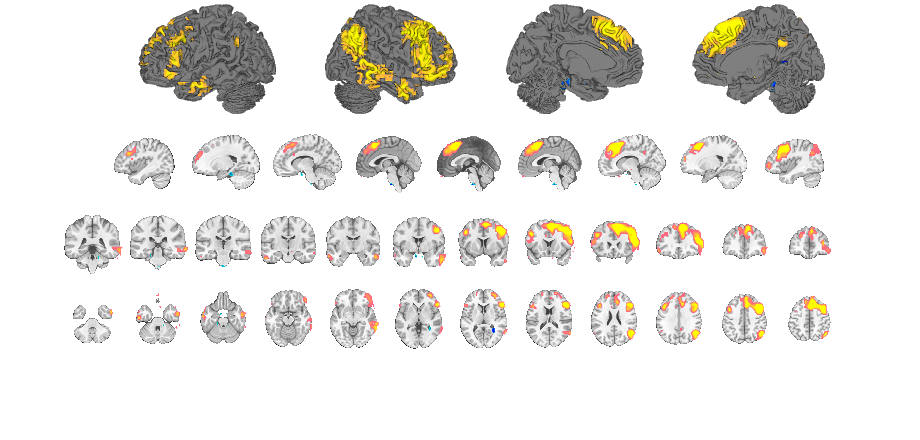

drawnow, snapnow


% it's even easier if we render the mean image:
o2 = addblobs(o2, mean_img);
drawnow, snapnow


Setting up fmridisplay objects
Compressed NIfTI files are not supported.


## MNISurf: Volume to Surface projection using default mappings

There are better ways to plot from MNI space to surfaces than direct vertex sampling based on the surface mesh coordinates. One generic method is known as MNISurf and is invoked in canlab core by specifying source spaces and target surfaces.

This is accomplished using the 'sourcespace' and  'targetsurface' options:

o2 = canlab_results_fmridisplay('freesurfer inflated');

Grouping contiguous voxels:  27 regions


o2 = addblobs(o2, t, 'sourcespace','MNI152NLin2009cAsym','targetsurface','fsaverage_164k');


The projection above was obtained by getting a voxelwise mapping from MNI152NLin2009cAsym space to the segmented MNI surface, aligning the MNI surface to the Conte69 surface in freesurfer and concatenating the transformations. The result is saved in a file in CanlabCore and is used when appropriate target and source surfaces are designated. The mapping isn't based on the location of the vertices of the freesurfer surface, but rather on their index. This is important because the vertex locations differ for different levels of surface inflation, but indices do not. They always correspond 1-to-1 across the same surface at whatever level of inflation you pick.

The documentation for this available in render_on_surface, which is invoked at the bottom of the stack by higher level functions like image_vector/montage.

As you can see, multiple source spaces are available, and two target surfaces. BigBrain does not yet exist because a surface segmentation of BigBrain is not available. There are some esoteric difficulties associated with this particular brain. 

#### Controlling rendering depth with 'srcdepth' option

You can also select what depth you want to sample your data from. Usually midthickness is the default in most packages, but for visualization here the default is to sample at 3 depths and average the results.

figure;
o2 = canlab_results_fmridisplay('freesurfer inflated');
o2 = t.montage(o2,'sourcespace','MNI152NLin2009cAsym','targetsurface','fsaverage_164k','srcdepth','pial');


figure;
o2 = canlab_results_fmridisplay('freesurfer inflated');
o2 = t.montage(o2,'sourcespace','MNI152NLin2009cAsym','targetsurface','fsaverage_164k','srcdepth','white');


Generally the default srcdepth argument is adequate.

There are better methods of volume to surface mapping though. The best method is known as **registration fusion**, and is available in the neuromaps python package, but is a bit more difficult to implement so it hasn't been added yet to canlab core. For more details on these methods, including registration fusion, refer to Wu et al. 2018 Human Brain Mapping. doi: 10.1002/hbm.24213

It's important to note that this kind of projection of paingen ata to surfaces from volumetric space is not the same as doing your analysis in surface space to begin with. The latter results in better intersubject alignment, larger activation foci, and stronger effects in the final surface projection. Surface projection is simply a handy way of visualizing volumetric data, not a way to benefit from the analytic advantages of surface analysis.

## Atlas mapping to surface

Several atlases have been defined in volumetric space with particular care for alignment. These atlas have predefined sourcespaces, and there's some built in awareness of target surfaces, so these will automatically render correctlly. Consider canlab2024,

canlab2024 = load_atlas('canlab2024_fsl6');
disp(canlab2024.space_description)

canlab2024 = load_atlas('canlab2024');
disp(canlab2024.space_description)

canlab2024 = canlab2024.threshold(0.2); % let's threshold for a better gray matter ribbon


Setting up fmridisplay objects
Compressed NIfTI files are not supported.


% It's available in multiple spaces, but you don't need to worry about
% wihch for rendering purposes because it's recorded internally.

Grouping contiguous voxels:  27 regions


figure;
canlab2024.montage('freesurfer inflated')

It's available in multiple spaces, but you don't need to worry about wihch for rendering purposes because it's recorded internally. However, we can overwrite it, which is useful to illustrate the kinds of subtle problems that arise when you're missampling surfaces, ones that are much easier to identify by eye in discrete parcellations than continuous activation maps.

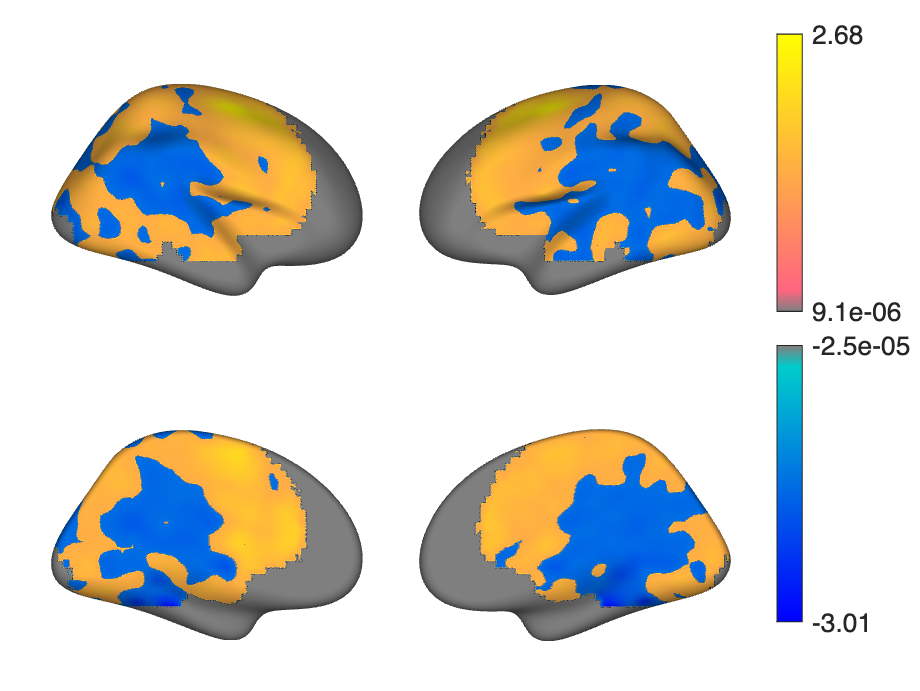

Grouping contiguous voxels:   1 regions


figure;
canlab2024.montage('sourcespace',[], 'freesurfer inflated');

even on big brain, which in the case of our contrast map above looked decent, the atlas does not look good without proper surface projection

Setting up fmridisplay objects
Compressed NIfTI files are not supported.


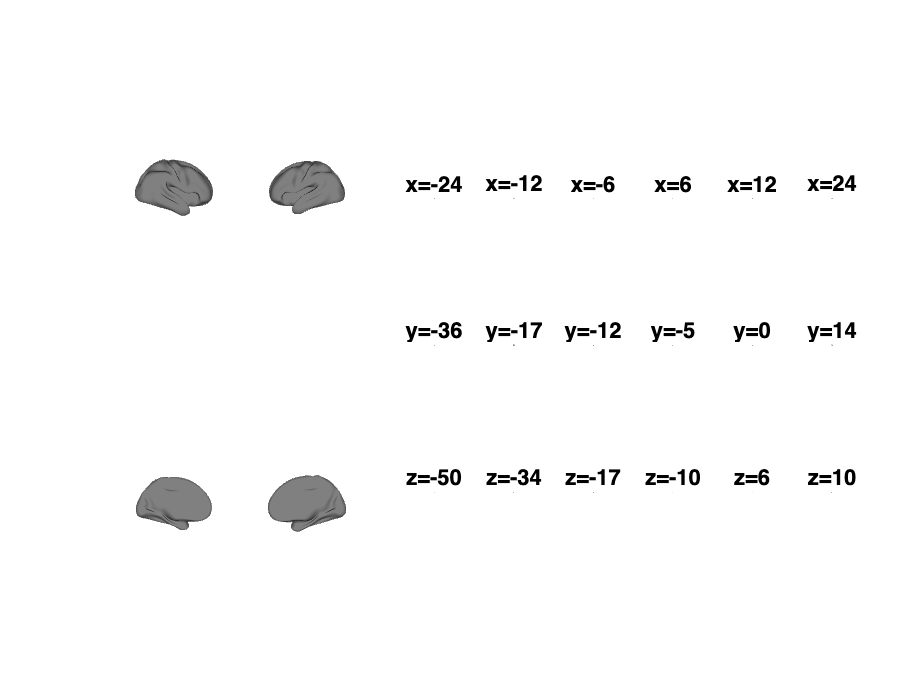

Unrecognized function or variable 'create_figure3'.

figure;
canlab2024.montage('full2')

it doesn't look any better on hcp surfaces, even though if you look at the volumetric data the atlas follows the gray matter ribbon very closely. You'd never want to publish a figure like this.

figure;
canlab2024.montage('sourcespace', [], 'full hcp')

But with surface projection enabled, the holes in the map go away, and things are a bit closer to being publication ready.

figure;
canlab2024.montage('sourcespace', 'MNI152NLin2009cAsym', 'full hcp')

% These concerns about mismatches between templates, whether surface or
% volumetric, affect atlas parcel definitions. If you look carefully at
% load_atlas' help you'll see that many atlases have options for selecting
% a source space, either fmriprep20, which is MNI152NLin2009cAsym, or fsl6,
% which MNI152NLin6Asym. This is to facilitate working with different data
% types. Atlases that were defined in surface space (e.g. Glasser) were
% projected to their target spaces using registration fusion, so they're a
% bit more accurate than these renderings you see here. For atlases defined
% in surface space you're best off rendering the surface data directly
% rather than taking the volumetric version of the surface data and trying
% to back project it. Something will always be lost in translation.

## Plotting surface data to surfaces

For the most part surface analysis is not supported by canlabCore, but for the sake of basic visualization I (BP) have started a new repo that currently has a couple of low level functions that may help to do things like plot surface formatted atlases to surface meshes. 

addpath(genpath('/home/bogdan/.matlab/canlab/canlabSurface'));

For the most part, Neuroimaging_Pattern_Masks (where all our atlases are), contains all the data needed to regenerate them from source materials. In the case of atlases defined in surface formats like Glasser et al's HCP MMP 1.0, that means the surface files are available, and you can render to surface meshes that match their vertex indicing.

This latter point is imporant. Vertices are not in the same order across all surfaces, even surfaces that sample the same space like fsaverage and HCP 32k. The corresponding surface should be clear from the filenames though. Let's start with glasser. Navigate to the Glasser atlas folder in Neuroimaging_Pattern_Masks and find the surface (gifti) files, Atlases_and_parcellations/2016_Glasser_Nature_HumanConnectomeParcellation/ You'll see they're called Glasser_2016.32k.[LR].label.gii. 32k indicates the HCP surface, so let's load it. Surfaces can be found in, CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/, and the gifti function comes from spm.

surfL = gifti(which('S1200.L.midthickness_MSMAll.32k_fs_LR.surf.gii'))
surfR = gifti(which('S1200.R.midthickness_MSMAll.32k_fs_LR.surf.gii'))

glasserL = gifti(which('Glasser_2016.32k.L.label.gii'))
glasserR = gifti(which('Glasser_2016.32k.L.label.gii'))

Notice how gifti files can either contain data or surface information. This separation is a feature because it allows you to sample the same data to multiple surfaces so long as they use the same coordinate system. Here we're sampling to an inflated surface, but you could just as easily sample to a midthickness surface, spherical surface, etc.

First thing we need to do is create an image and render some surfaces.

figure;
clf

ax1 = subplot(2,2,1);
s1 = render_surface(surfL.vertices, surfL.faces, ax1);

ax2 = subplot(2,2,2);
s2 = render_surface(surfR.vertices, surfR.faces, ax2, 'flip');

ax3 = subplot(2,2,3);
s3 = render_surface(surfL.vertices, surfL.faces, ax3, 'flip');

ax4 = subplot(2,2,4);
s4 = render_surface(surfR.vertices, surfR.faces, ax4);

% now let's get a colormap to use when plotting. Surface label files
% contain this information as metadata,

cmapL = glasserL.labels.rgba(:,1:3);
cmapR = glasserR.labels.rgba(:,1:3);

% Now we need to plot data to these surfaces. Note, this function was
% adapted from canlabCore's plot_to_surf. The documentation has not been
% updated, and may not be accurate, but it should look very similarly.
plot_surf_to_surf(glasserL.cdata, s1, 'colormap', cmapL, 'indexmap');
plot_surf_to_surf(glasserR.cdata, s2, 'colormap', cmapR, 'indexmap');
plot_surf_to_surf(glasserL.cdata, s3, 'colormap', cmapL, 'indexmap');
plot_surf_to_surf(glasserR.cdata, s4, 'colormap', cmapR, 'indexmap');

sgtitle('HCP MMP 1.0','FontWeight','bold','fontsize',16);

% You can get a nicer layout by using tiledlayout + nexttile() instead of 
% subplots, but I used subplots because it's simpler.

## Plotting grayordinate data

Plotting grayordinate data from cifti files isn't all that different from plotting gifti data. The main difficulty arises from extracting subcortical data and plotting it, but we're also going to dispense with manual construction of our plotting layout and just use a convenience function here.

% You can look at the source code for this file you want to create some new
% custom layouts. o2 represents the surface objects while o3 represents the 
% subcortical surfaces. This function used tiledlayout instead of subplots
% and t0 is a handle to this layout which lets you modify appearance.
figure;
[o2,o3, t0] = create_compact_hcp_grayordinate_figure('overlay', 'fsl6_hcp_template.nii.gz', 'nocolorbar');

% Now let's import a cifti atlas. If you don't have this atlas you need to
% run create_CANLab2024_atlas_prep.sh and create_CANLab2024_atlas_cifti.sh
% in Neuroimaging_Pattern_Masks/Atlases_and_parcellations/2024_CANLab_atlas/src
% (as well as load_atlas('canlab2024_fsl6'), but if you're following along
% you'll have already invoked that above). You also need cifti_read from 
% https://github.com/Washington-University/cifti-matlab
addpath(genpath('/home/bogdan/.matlab/cifti-matlab'));
cifti_obj = cifti_read(which('CANLab2024_MNI152NLin6Asym_coarse_2mm.dlabel.nii'));

% cifti files are saved as xml files + a nifti component for volumetric
% data representation, and it can be a pain to map some components from the
% vectorized representation to their structures. I've created some utility
% functions to facilitate this.
canlab2024_cii = get_cifti_data(which('CANLab2024_MNI152NLin6Asym_coarse_2mm.dlabel.nii'));

% colormaps are stored in very similar format as gifti files
labels = cifti_obj.diminfo{2}.maps.table(2:end);
cmap = zeros(length(labels),3);
for i = 1:length(labels)
    cmap(i,:) = labels(i).rgba(1:3);
end

% extracting subcortical data is quite annoying, so I've created a function
% to facilitate it that returns an fmri_data object.
vol = extract_vol_from_cifti(cifti_obj);

% Now we can plot in similar manner to the gifti images. Note, input must
% be a column vector.
plot_surf_to_surf(canlab2024_cii.cortex_left', o2.surface{1}.object_handle, 'colormap', cmap, 'indexmap');
plot_surf_to_surf(canlab2024_cii.cortex_right', o2.surface{2}.object_handle, 'colormap', cmap, 'indexmap');
plot_surf_to_surf(canlab2024_cii.cortex_left', o2.surface{3}.object_handle, 'colormap', cmap, 'indexmap');
plot_surf_to_surf(canlab2024_cii.cortex_right', o2.surface{4}.object_handle, 'colormap', cmap, 'indexmap');

% now let's plot the subcortical data
n_ctx_rois = unique([canlab2024_cii.cortex_left, canlab2024_cii.cortex_right]);
vol.montage(o3,'indexmap',cmap)

% Now let's add a title that doesn't overlap the plots by manipulating the
% tile layouts y-axis length, and adjust the image width for a more compact
% display
t0.Position(4) = 0.85;

pos = get(gcf,'Position');
set(gcf,'Position',[pos(1:2), 420, 420]);

t = sgtitle('CANLab2024','FontSize',16,'fontweight','bold');